mainFolder = fullfile(pwd, "AudioManip-Main");

% Ensure main folder exists
if ~exist(mainFolder, 'dir')
    mkdir(mainFolder);
end

% Load processed normal and abnormal files
normalFilesSVM = dir(fullfile(mainFolder, "sounddata*.wav"));
abnormalFilesSVM = dir(fullfile(mainFolder, "abnormalsounddata*.wav"));

% Convert file names into string arrays and sort them
normalListSVM = string({normalFilesSVM.name});
abnormalListSVM = string({abnormalFilesSVM.name});

natsortfiles(normalListSVM);
natsortfiles(abnormalListSVM);

% Number of files - numFIlesSVM  = Number of samples for training/testing %
% Desired Time Frame of Sound Files - fixedLength = Current Sample Rate is%
% 16000 Hz.                                                               %
% Channel number for audio input - chNum = Out of 7 channels, channel 1 is%
% chosen.                                                                 %

numFilesSVM = 100;
fixedLength = 16000;
chNum = 1;

normWaveformsSVM = zeros(numFilesSVM, fixedLength);

% Process each file: load, convert to mono, trim/pad, normalize
for i = 1:numFilesSVM
    fileName = fullfile(mainFolder, normalListSVM(i));
    if exist(fileName, 'file')
        [y, Fs] = audioread(fileName);
        if size(y, 2) > 1
            y = mean(y, 2);
        end
        if length(y) > fixedLength
            y = y(1:fixedLength);
        elseif length(y) < fixedLength
            y = [y; zeros(fixedLength - length(y), 1)];
        end
        y = (y - mean(y)) / std(y);
        normWaveformsSVM(i, :) = y';
    else
        warning("Processed file %s not found.", fileName);
    end
end

fprintf("Normal Waveforms Processed!");

Normal Waveforms Processed!


abnormWaveformsSVM = zeros(numFilesSVM, fixedLength);

% Process each file: load, convert to mono, trim/pad, normalize
for i = 1:numFilesSVM
    fileName = fullfile(mainFolder, abnormalListSVM(i));
    if exist(fileName, 'file')
        [y, Fs] = audioread(fileName);
        if size(y, 2) > 1
            y = mean(y, 2);
        end
        if length(y) > fixedLength
            y = y(1:fixedLength);
        elseif length(y) < fixedLength
            y = [y; zeros(fixedLength - length(y), 1)];
        end
        y = (y - mean(y)) / std(y);
        abnormWaveformsSVM(i, :) = y';
    else
        warning("Processed file %s not found.", fileName);
    end
end

fprintf("Abnormal Waveforms Processed!");

Abnormal Waveforms Processed!

allWaveformsSVM = [normWaveformsSVM; abnormWaveformsSVM];
allLabelsSVM = [zeros(1, size(normWaveformsSVM,1)), ones(1, size(abnormWaveformsSVM,1))];



% Preallocate feature matrix and labels for pre-made feature route
normFeaturesSVM = zeros(numFilesSVM, 21);
abnFeaturesSVM = zeros(numFilesSVM, 21);

% Extract features for each audio file
for i = 1:numFilesSVM
    fileName = fullfile(mainFolder, normalListSVM(i));
    if exist(fileName, 'file')
        timeFreqFeaturesSVM = generateAudioFeatures(fileName, chNum);
        fftFeaturesSVM = generateFFTFeatures(fileName, chNum, 1024);
        featureVectorSVM = [table2array(timeFreqFeaturesSVM), table2array(fftFeaturesSVM)];
        normFeaturesSVM(i, :) = featureVectorSVM;
    else
        warning("Feature extraction skipped for missing file: %s", fileName);
    end
end

for i = 1:numFilesSVM
    fileName = fullfile(mainFolder, abnormalListSVM(i));
    if exist(fileName, 'file')
        abntimeFreqFeaturesSVM = generateAudioFeatures(fileName, chNum);
        abnfftFeaturesSVM = generateFFTFeatures(fileName, chNum, 1024);
        abnfeatureVectorSVM = [table2array(abntimeFreqFeaturesSVM), table2array(abnfftFeaturesSVM)];
        abnFeaturesSVM(i, :) = abnfeatureVectorSVM;
    else
        warning("Feature extraction skipped for missing file: %s", fileName);
    end
end

allFeaturesSVM = [normFeaturesSVM; abnFeaturesSVM];

% Create feature table with labels
featureNamesSVM = [abntimeFreqFeaturesSVM.Properties.VariableNames, abnfftFeaturesSVM.Properties.VariableNames];
featureTableSVM = array2table(allFeaturesSVM, 'VariableNames', featureNamesSVM);
featureTableSVM.Label = allLabelsSVM';

% Convert features to numeric matrix
featureMatrixSVM = table2array(featureTableSVM(:, 1:end-1));

disp("All features processed and ready for SVM analysis!");

All features processed and ready for SVM analysis!


SVM Accuracy: 55.00%


Iteration Number 1.000000

     5     5
     4     6



SVM Accuracy: 37.50%


Iteration Number 2.000000

     8    12
    13     7



SVM Accuracy: 51.67%


Iteration Number 3.000000

    20    10
    19    11



SVM Accuracy: 46.25%


Iteration Number 4.000000

    19    21
    22    18



SVM Accuracy: 49.00%


Iteration Number 5.000000

    25    25
    26    24



SVM Accuracy: 51.67%


Iteration Number 6.000000

    35    25
    33    27



SVM Accuracy: 55.00%


Iteration Number 7.000000

    34    36
    27    43



SVM Accuracy: 55.00%


Iteration Number 8.000000

    38    42
    30    50



SVM Accuracy: 48.89%


Iteration Number 9.000000

    56    34
    58    32



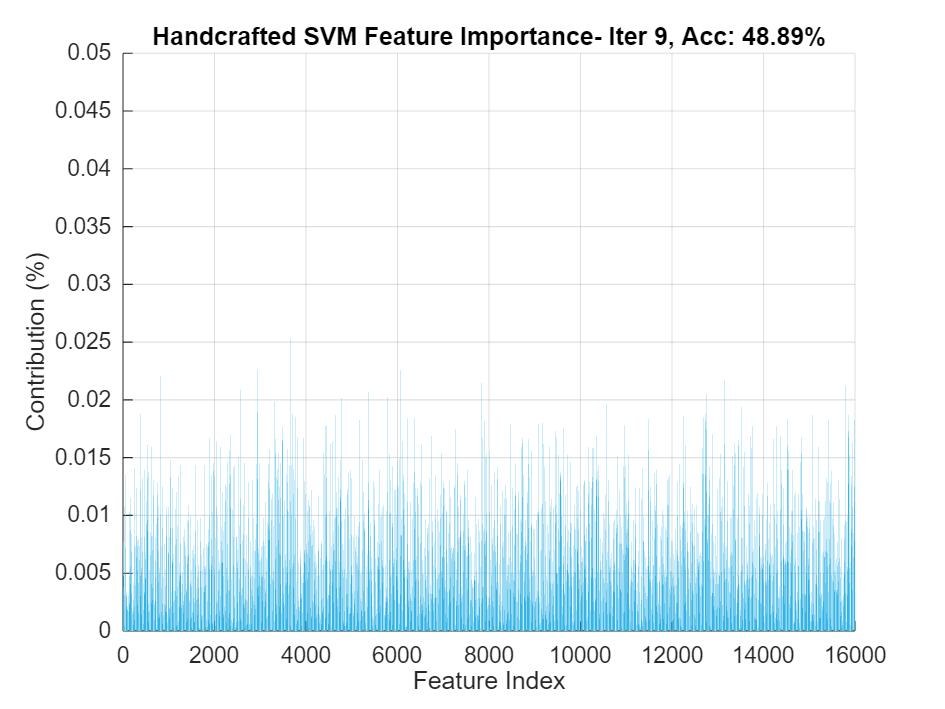


% Note: I know this portion of the code is a bit sloppy with the          % 
% transposition of the label arrays YTrain and YTest, but since the lines %
% of code all work correctly I dare not touch it for now. That being said,%
% rearrange any of this as you see fit if you have similar and/or more    %
% knowledge on how this should be working.                                %


perfMod = 0.9;

for perfModiter = 0.1:0.1:perfMod
    % Split Data 
    cv = cvpartition(allLabelsSVM, 'HoldOut', perfModiter);
    XTrain = allWaveformsSVM(training(cv), :);
    YTrain = allLabelsSVM(training(cv));
    XTest = allWaveformsSVM(test(cv), :);
    YTest = allLabelsSVM(test(cv));
    
    % Train SVM Model
    svmModel = fitcsvm(XTrain, YTrain', 'KernelFunction', 'linear', 'Standardize', true);
    
    % Predict on Test Data
    YPred = predict(svmModel, XTest);
    
    % Accuracy
    accuracy = sum(YPred' == YTest) / length(YTest);
    fprintf('SVM Accuracy: %.2f%%\n', accuracy * 100);
    fprintf('Iteration Number %f%\n', perfModiter/0.1);
    csvm=confusionmat(YTest, YPred);
    disp(csvm);

    svmWeights = svmModel.Beta;
    featureContributionsvm = abs(svmWeights) / sum(abs(svmWeights)) * 100;
    bar(featureContributionsvm);
    xlabel('Feature Index');
    ylabel('Contribution (%)');
    title('Handcrafted SVM Feature Importance');
    grid on;

     % Create bar plot that updates smoothly
    clf; % Clear figure for fresh plot
    hold on;

    % Animate the bars growing
    numFeaturessvm = length(featureContributionsvm);
    barHeights = zeros(1, numFeaturessvm);
    numSteps = 20;  % Number of steps for animation

    for step = 1:numSteps
        % Smoothly update bar heights
        barHeights = featureContributionsvm * (step / numSteps);
        bar(barHeights, 'FaceColor', [0.2, 0.7, 0.9]);

        % Labels and formatting
        xlabel('Feature Index');
        ylabel('Contribution (%)');
        title(sprintf('Handcrafted SVM Feature Importance- Iter %.0f, Acc: %.2f%%', perfModiter/0.1, accuracy * 100));
        axis([0 numFeaturessvm+1 0 .05]);
        grid on;
        drawnow; 
    end

    hold off;

end